% *CÓDIGO CON IMPLEMENTACIÓN DE TRAYECTORIAS*
%Codigo siulacion C. inversa:
clc; clear; close all;
format short;

%% 1. PARÁMETROS DEL ROBOT (Longitudes en mm)
L1 = 195;  
L2 = 180; 
L3 = 125;

% Parámetros DH base [theta, d, a, alpha]
DH_params = [
    0, L1, 0,  pi/2;  % Juntura 1
    0, 0,  L2, 0;     % Juntura 2
    0, 0,  L3, 0      % Juntura 3
];

%% 2. ENTRADA DE USUARIO Y CINEMÁTICA INVERSA
fprintf('--- Cálculo de Cinemática Inversa ---\n');

--- Cálculo de Cinemática Inversa ---


X = input('Ingrese X: ');
Y = input('Ingrese Y: ');
Z = input('Ingrese Z: ');
P_obj = [X; Y; Z];

% Distancia radial y ángulo de base
r = sqrt(X^2 + Y^2);
theta1 = atan2(Y, X);

% Cálculo de ley de cosenos para Theta3
c3 = (X^2 + Y^2 + (Z-L1)^2 - L2^2 - L3^2) / (2*L2*L3);

if abs(c3) > 1
    error('El punto está fuera del espacio de trabajo.');
end

% Solución 1: CODO ARRIBA
th3_up = atan2(sqrt(1-c3^2), c3);
th2_up = atan2((Z-L1), r) - atan2(L3*sin(th3_up), L2 + L3*cos(th3_up));
q_up = [theta1; th2_up; th3_up];

% Solución 2: CODO ABAJO
th3_dw = atan2(-sqrt(1-c3^2), c3);
th2_dw = atan2((Z-L1), r) - atan2(L3*sin(th3_dw), L2 + L3*cos(th3_dw));
q_dw = [theta1; th2_dw; th3_dw];

% Mostrar resultados en consola
fprintf('\nANGULOS CALCULADOS (Grados):\n');


ANGULOS CALCULADOS (Grados):


fprintf('Theta 1: %.2f\n', rad2deg(theta1));

Theta 1: 45.00


fprintf('Configuración CODO ARRIBA: Theta2 = %.2f, Theta3 = %.2f\n', rad2deg(th2_up), rad2deg(th3_up));

Configuración CODO ARRIBA: Theta2 = -75.58, Theta3 = 114.97


fprintf('Configuración CODO ABAJO:  Theta2 = %.2f, Theta3 = %.2f\n', rad2deg(th2_dw), rad2deg(th3_dw));

Configuración CODO ABAJO:  Theta2 = 7.80, Theta3 = -114.97


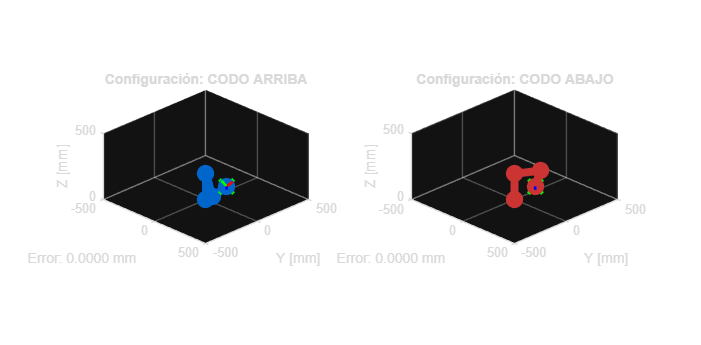


%% 3. VISUALIZACIÓN GRÁFICA
fig = figure('Color', 'w', 'Name', 'Resultados Cinemática Inversa', ...
             'NumberTitle', 'off', 'Units', 'normalized', 'Position', [0.1 0.1 0.8 0.7]);

% Subplot 1: Solución Codo Arriba
ax1 = subplot(1, 2, 1);
graficar_robot(ax1, DH_params, q_up, P_obj, 'Configuración: CODO ARRIBA', [0 0.4 0.8]);

% Subplot 2: Solución Codo Abajo
ax2 = subplot(1, 2, 2);
graficar_robot(ax2, DH_params, q_dw, P_obj, 'Configuración: CODO ABAJO', [0.8 0.2 0.2]);


%% 4. FUNCIONES AUXILIARES
function [O, T] = calcular_fk(DH, q)
    T = eye(4);
    O = zeros(size(DH,1)+1, 3);
    O(1,:) = [0 0 0];
    for j = 1:size(DH,1)
        th = DH(j,1) + q(j); d = DH(j,2); a = DH(j,3); al = DH(j,4);
        A = [ cos(th) -sin(th)*cos(al)  sin(th)*sin(al)  a*cos(th);
              sin(th)  cos(th)*cos(al) -cos(th)*sin(al)  a*sin(th);
              0        sin(al)           cos(al)          d;
              0        0                 0                1 ];
        T = T * A;
        O(j+1,:) = T(1:3,4).';
    end
end

function graficar_robot(ax, DH, q, P_obj, titulo, color_robot)
    [O, T_ee] = calcular_fk(DH, q);
    pEE = T_ee(1:3,4);
    
    hold(ax, 'on'); grid(ax, 'on'); axis(ax, 'equal');
    view(ax, 45, 25);
    xlabel(ax, 'X [mm]'); ylabel(ax, 'Y [mm]'); zlabel(ax, 'Z [mm]');
    title(ax, titulo);
    
    % Límites dinámicos basados en la longitud total
    limit = sum(DH(:,3)) + DH(1,2);
    axis(ax, [-limit limit -limit limit 0 limit]);

    % Dibujar Objetivo
    plot3(ax, P_obj(1), P_obj(2), P_obj(3), 'gx', 'MarkerSize', 15, 'LineWidth', 3);
    
    % Dibujar Robot
    plot3(ax, O(:,1), O(:,2), O(:,3), '-o', 'LineWidth', 6, 'MarkerSize', 7, 'Color', color_robot);
    
    % Ejes en el extremo (TCP)
    R = T_ee(1:3,1:3);
    s = 60; % Escala de los ejes
    quiver3(ax, pEE(1), pEE(2), pEE(3), R(1,1)*s, R(2,1)*s, R(3,1)*s, 'r', 'LineWidth', 2);
    quiver3(ax, pEE(1), pEE(2), pEE(3), R(1,2)*s, R(2,2)*s, R(3,2)*s, 'g', 'LineWidth', 2);
    quiver3(ax, pEE(1), pEE(2), pEE(3), R(1,3)*s, R(2,3)*s, R(3,3)*s, 'b', 'LineWidth', 2);
    
    % Mostrar error en el título del eje
    dist = norm(P_obj - pEE);
    xlabel(ax, sprintf('Error: %.4f mm', dist));
end

%% 5. GENERACIÓN DE TRAYECTORIA (Perfil Trapezoidal Tipo 2)
fprintf('\n--- Cálculo de Velocidades de Crucero ---\n');


--- Cálculo de Velocidades de Crucero ---



% 1. Definir Posición Inicial (Home) y Final (Deseada) en radianes
qi = [0; 0; 0];       % Asumimos Home en 0,0,0
qf = q_up;            % Usaremos la solución codo arriba como destino

% 2. Definir Tiempo Total del movimiento
tf = 5;               % Tiempo deseado en segundos (puedes cambiarlo)

% 3. Aplicar las fórmulas de la foto para cada articulación
% Preasignar memoria
qc_dot = zeros(3,1);  % Velocidad de crucero
tc = zeros(3,1);      % Tiempo de aceleración (tu tc)
qc_ddot = zeros(3,1); % Aceleración

for i = 1:3
    delta_q = qf(i) - qi(i);
    
    if abs(delta_q) > 1e-4 % Si la articulación se mueve
        
        % Condición: (qf-qi)/tf < qc_dot <= 2*(qf-qi)/tf
        % Elegimos un valor en la mitad (1.5) para cumplir tu límite
        qc_dot(i) = 1.5 * (delta_q / tf); 
        
        % Tu fórmula 1: tc = (qi - qf + qc_dot * tf) / qc_dot
        tc(i) = (qi(i) - qf(i) + qc_dot(i) * tf) / qc_dot(i);
        
        % Tu fórmula 2: qc_ddot = qc_dot^2 / (qi - qf + qc_dot * tf)
        qc_ddot(i) = (qc_dot(i)^2) / (qi(i) - qf(i) + qc_dot(i) * tf);
        
    else
        % Si no se mueve, todo es 0
        qc_dot(i) = 0; tc(i) = 0; qc_ddot(i) = 0;
    end
end

% Imprimir resultados
for i = 1:3
    fprintf('Joint %d: Vel. Crucero = %.3f rad/s, Acel = %.3f rad/s^2, Tiempo de acel (tc) = %.2f s\n', ...
        i, qc_dot(i), qc_ddot(i), tc(i));
end

Joint 1: Vel. Crucero = 0.236 rad/s, Acel = 0.141 rad/s^2, Tiempo de acel (tc) = 1.67 s
Joint 2: Vel. Crucero = -0.396 rad/s, Acel = -0.237 rad/s^2, Tiempo de acel (tc) = 1.67 s
Joint 3: Vel. Crucero = 0.602 rad/s, Acel = 0.361 rad/s^2, Tiempo de acel (tc) = 1.67 s


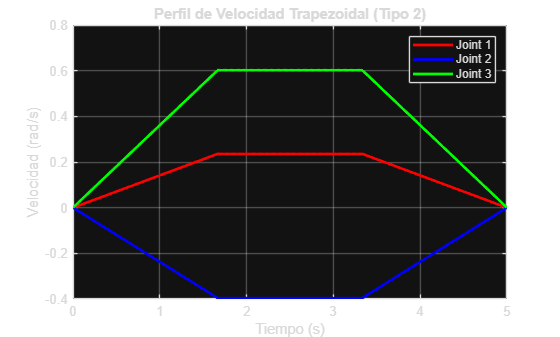


%% 6. (Opcional) GRÁFICA DEL PERFIL DE VELOCIDADES
% Esto te ayudará a verificar que el trapecio se forma correctamente
t = linspace(0, tf, 500);
v_t = zeros(3, length(t));

for i=1:3
    if qc_dot(i) ~= 0
        for k=1:length(t)
            if t(k) <= tc(i) % Tramo 1: Aceleración
                v_t(i,k) = qc_ddot(i) * t(k);
            elseif t(k) <= tf - tc(i) % Tramo 2: Crucero constante
                v_t(i,k) = qc_dot(i);
            else % Tramo 3: Desaceleración
                t_dec = t(k) - (tf - tc(i));
                v_t(i,k) = qc_dot(i) - qc_ddot(i) * t_dec;
            end
        end
    end
end

figure('Name', 'Perfil de Velocidad de Crucero', 'Color', 'w');
plot(t, v_t(1,:), 'r', t, v_t(2,:), 'b', t, v_t(3,:), 'g', 'LineWidth', 2);
title('Perfil de Velocidad Trapezoidal (Tipo 2)');
xlabel('Tiempo (s)'); ylabel('Velocidad (rad/s)');
legend('Joint 1', 'Joint 2', 'Joint 3'); grid on;


%% 7. GENERACIÓN DE LA TRAYECTORIA DE POSICIONES q(t)
% Crear un vector de tiempo para la animación
n_steps = 100;
t_sim = linspace(0, tf, n_steps); 
q_t = zeros(3, n_steps); % Matriz de posiciones articulares

for i = 1:3
    delta_q = qf(i) - qi(i);
    if abs(delta_q) > 1e-4
        for k = 1:n_steps
            tk = t_sim(k);
            % Integración del perfil trapezoidal para obtener posición q(t)
            if tk <= tc(i) % Fase Aceleración
                q_t(i,k) = qi(i) + 0.5 * qc_ddot(i) * tk^2;
            elseif tk <= (tf - tc(i)) % Fase Crucero
                q_t(i,k) = qi(i) + qc_ddot(i) * tc(i) * (tk - tc(i)/2);
            else % Fase Desaceleración
                q_t(i,k) = qf(i) - 0.5 * qc_ddot(i) * (tf - tk)^2;
            end
        end
    else
        q_t(i,:) = qi(i); % Permanecer estático si no hay movimiento
    end
end

%% 8. ANIMACIÓN DEL MOVIMIENTO DEL ROBOT Y EFECTOR
fig_anim = figure('Color', 'w', 'Name', 'Simulación de Movimiento', 'Units', 'normalized', 'Position', [0.2 0.2 0.6 0.6]);
ax_anim = axes('Parent', fig_anim);
hold(ax_anim, 'on'); grid(ax_anim, 'on'); axis(ax_anim, 'equal');
view(ax_anim, 45, 25);
xlabel('X [mm]'); ylabel('Y [mm]'); zlabel('Z [mm]');
title('Trayectoria del Robot hacia el Objetivo');

% Límites de la gráfica
limit_sim = sum(DH_params(:,3)) + DH_params(1,2);
axis(ax_anim, [-limit_sim limit_sim -limit_sim limit_sim 0 limit_sim]);

% Dibujar el punto objetivo
plot3(ax_anim, P_obj(1), P_obj(2), P_obj(3), 'gx', 'MarkerSize', 12, 'LineWidth', 2, 'DisplayName', 'Objetivo');

% Inicializar objetos gráficos
h_robot = plot3(ax_anim, 0, 0, 0, '-o', 'LineWidth', 5, 'MarkerSize', 6, 'Color', [0.2 0.6 0.2], 'MarkerFaceColor', 'k');
h_trayectoria = plot3(ax_anim, 0, 0, 0, 'r-', 'LineWidth', 1.5); % Estela del efector
h_punto_actual = plot3(ax_anim, 0, 0, 0, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 6);

% Almacenar posiciones del efector para la estela
pos_estela = zeros(3, n_steps);

% Bucle de animación
fprintf('\nIniciando animación...\n');


Iniciando animación...


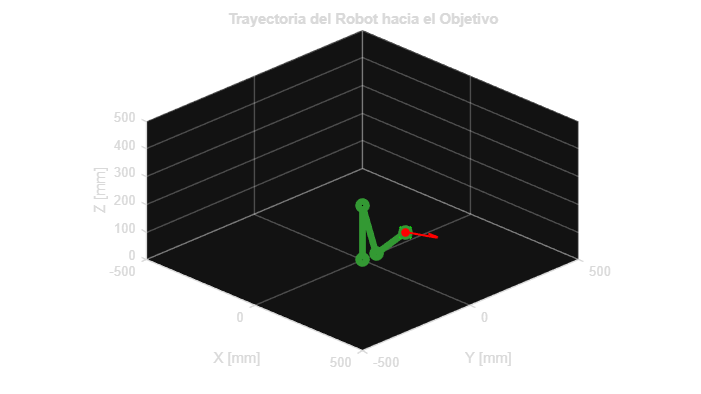

for k = 1:n_steps
    % Calcular cinemática actual
    [O_curr, T_curr] = calcular_fk(DH_params, q_t(:,k));
    pos_actual = T_curr(1:3,4);
    pos_estela(:,k) = pos_actual;
    
    % Actualizar Robot (Eslabones y articulaciones)
    set(h_robot, 'XData', O_curr(:,1), 'YData', O_curr(:,2), 'ZData', O_curr(:,3));
    
    % Actualizar Estela (Trayectoria recorrida)
    set(h_trayectoria, 'XData', pos_estela(1,1:k), 'YData', pos_estela(2,1:k), 'ZData', pos_estela(3,1:k));
    
    % Actualizar punto rojo en el TCP
    set(h_punto_actual, 'XData', pos_actual(1), 'YData', pos_actual(2), 'ZData', pos_actual(3));
    
    % Refrescar y controlar velocidad
    drawnow limitrate;
    pause(tf/n_steps); 
end


fprintf('Simulación finalizada.\n');

Simulación finalizada.
